# Computer Exercise 3 - Group 17

## Load Image

Let's read the image and plot it.

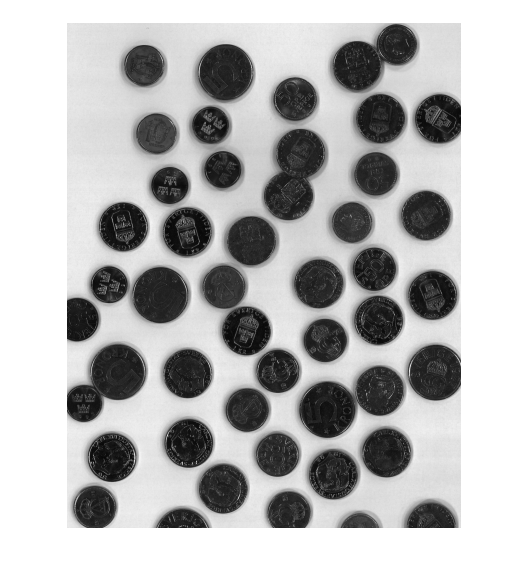

clear;
I = imread('coins.tif');
figure;
imshow(I);

The image has a distinct foreground with low intensity values and a distinct background with high intensity values. The coins (foreground) are dark circles with some light outlines in their centers which are the designs of the coin face. The background is a mostly uniform light grey color.

## Examine image histogram

Let's plot the histogram and exam the image further.

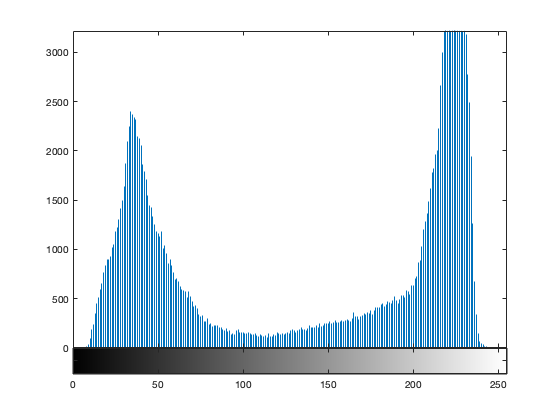

figure; 
imhist(I);

We can see that their are two distinct peaks which corresponds to what we see in the image. This is the ideal scenario for performing a threshold segmentation. The dark coins are represented towards the low end of the histogram while the light background is represented towards the high end of the histogram. There is a valley inbetween the two peaks.

## Segment foreground and background.

To perfrom the segmentation with matlab, we start with the **graythresh **function. This function finds the a global threshold value between 0 and 1 using *Otsu's method*. This method reduces intraclass variance of the white and black pixels of the binarized image. The range of 0 to 1 corresponds to where on the histogram the split occurs- so for uint8, a threshold of .5 would correspond to approximately 128. 

T = graythresh(I);

The global threshold, $T$, was found to be *.5059 *which corresponds to an intensity value of 129. We will pass this value to the the function **im2bw, **along with the image, and receive a binarized copy of the image. All pixel values below 129 will be made black, and all greater than or equal to 129 will be made white.

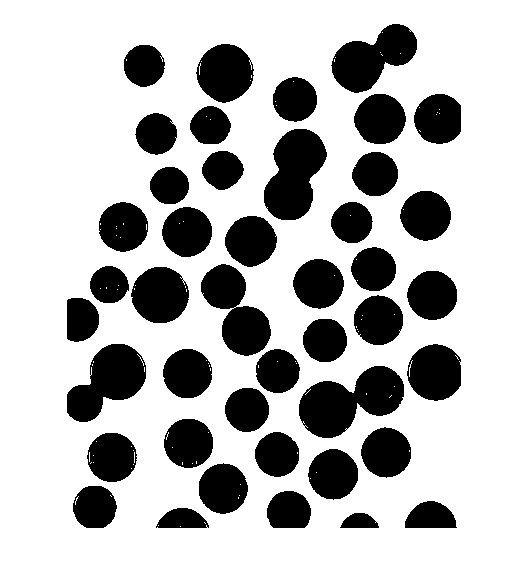

binarized = imbinarize(I, T);
figure; 
imshow(binarized);

Notice in the image that there is some noise inside of the black circles. Recall this is the design of the face of the coin which had some lighter outlines. To remove these and make the circles completely black, we will apply a median filter.

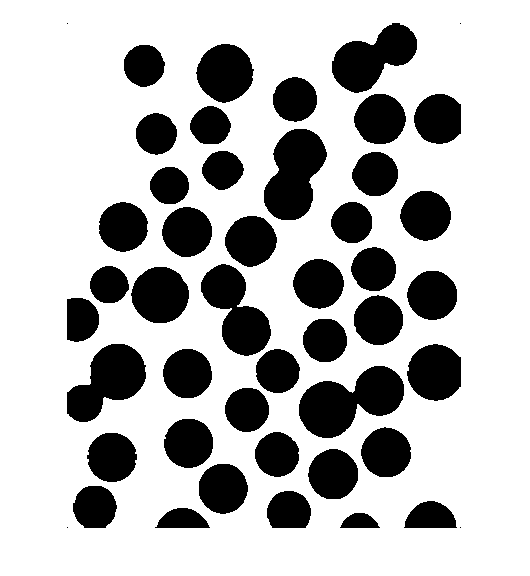

binarized_filtered = medfilt2(binarized);
figure; 
imshow(binarized_filtered);

We see that the median filter does a good job of removing noise. 

Our output image is a binary image, also known as a mask, where the black pixels represent the area where coins are found and the white pixels represent ares which are considered the background.

## Detect coin centers - Distance Transform

Once an image is segmented and we have a binary mask, the next step is to start identifying objects. A common way to do this is to try and find center points in the mask. Each center point that is found is thought to represent an object.

To find a center point, we use the distance transform, which for a binary image, calculates the distance from every black pixel to the closest white pixel. We use these distances to find local maxima and consider these points to be center points. 

This can be thought of as building a radius- as you "walk" from the border between the white background and the black circle towards the center of a circle, each subsequent step is 1 pixel further from the border. This distance is gradually increasing. However, when we get to the center and continue walking "out", the distance starts to decrease. Therefore, the center point is the point of maximum distance, or the radius.

We use the function **bwdist** to calculate the distance transform and get back a matrix of distance values. Any pixel that is white has a value of zero and any pixel that is black, now has a value equal to the distance to the closest white pixel.

Also, note that we are using *cityblock *distance instead of euclidean distance. This is a choice based on experimentation- the default euclidean distance metric had produced some oversegmented objects. I believe the *chessboard *and *cityblock *distances have less precision than euclidean which helps us avoid oversegmentation. The oversegmentation occured in areas of high overlap of the coins. 

dist_transformed = bwdist(binarized_filtered, "cityblock");

We can represent the distance transform visually by displaying it as a gray scale image. The largest distance value will be represented as white, the lowest distance as black, and values in between as shades of grey.

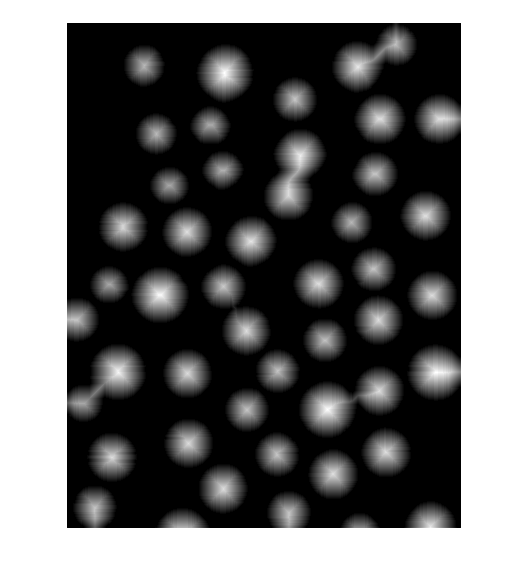

figure;
imshow(dist_transformed,[]); % equivalent to imshow(mat2gray(Idist));

The black areas represent the background, the dark greys are values close to the border of one of the coins, light grey is close to the center points, and the white points are centers of coins.

We can also visualize this using a 3d graph which shows the center points as the various peaks of the graph. 

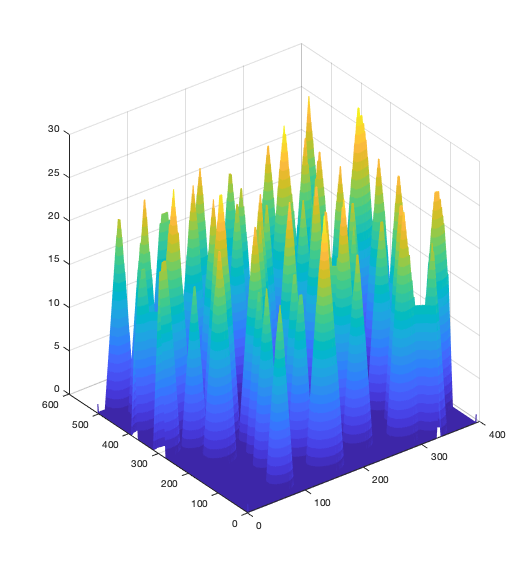

mesh(dist_transformed);

## Object Boundaries - Watershed

We now convert our distance matrix into objects or components. To do this we use the watershed transform. Let us first start with another 3d graph using the distance matrix, except we are going to use it's negative inversion.

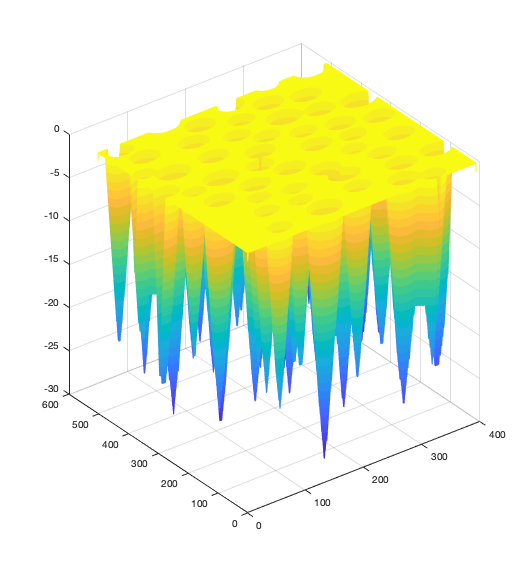

mesh(-dist_transformed);

Before we shoed the distance transform as a series of peaks, but we can now think of it as a series of water basins. Conceptually, the watershed transform fills these basins with water. When the water from different basins meet, we create a boundary and mark these as objects. The algorithm has more details regarding merging regions (dealing with all the local minima) which we will not get into.

To perform the watershed we use the *watershed* function of matlab which by default uses 8-connectivity. Then we display it as a greyscale image.

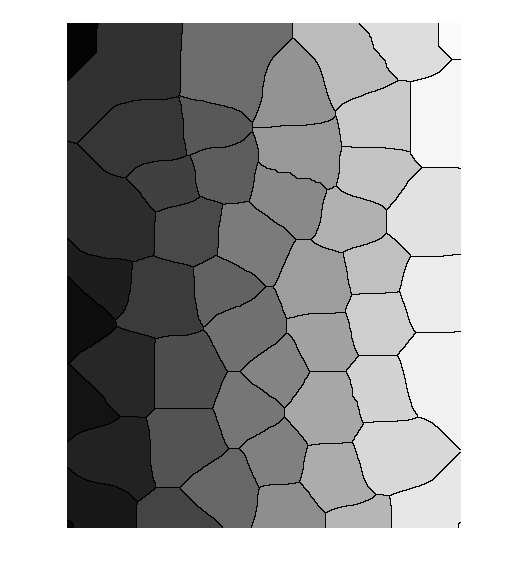

watershed_transformed = watershed(-dist_transformed);
figure;
imshow(watershed_transformed,[]);

We see here that there are clear boundaries created. The image looks like dried clay in the dessert, where each clump is a solid color, shade of grey. The clumps represent the merged components or objects found using the watershed algorithm. The boundary line separating all the components is pure black while each component is a shade of grey.

## Combine boundaries with image mask to produce segmented objects

We now combine the output of the methods we have used so far. The binary mask shows where the coins are and the watershed boundary shows the various regions. We can use the regions generated by the watershed to segment the mask. To do this we set the pixels of the watershed image to black which are white in the binary mask image. Recall that the mask image has white for the background and black where the coins are. We can then view the output of this in greyscale

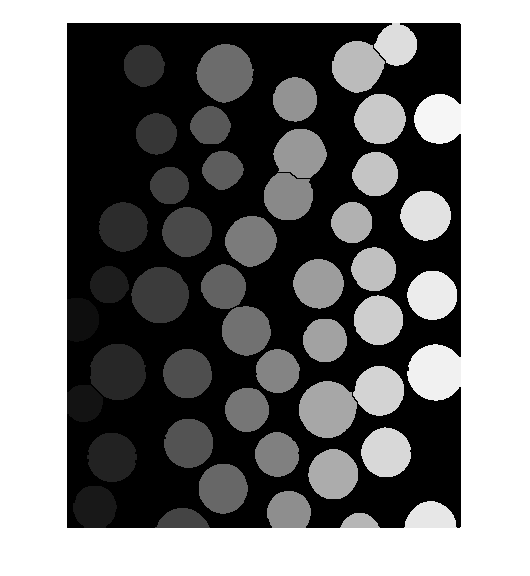

segmented_mask = watershed_transformed; % make a new copy so we dont alter the original
segmented_mask(binarized_filtered) = 0;
figure;
imshow(segmented_mask,[]);

## Label Objects

We now have an image containing distinct components, each of which is separated with black pixels and fully contained. Each component is a unique solid intensity, which means each component is "labeled". We can use the *label2rgb* function of matlab to label each component as a color.

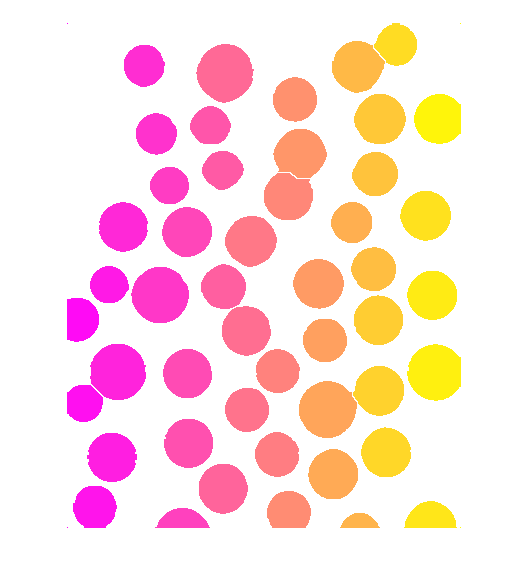

labeled_image = label2rgb(segmented_mask,'spring');
figure;
imshow(labeled_image);

## Lastly, find properties of objects

We use the matlab function *regionprops *on the labeled image. We select MajorAxisLength as the only property that we are interested in which seem to be the closest to the radii of the coins.

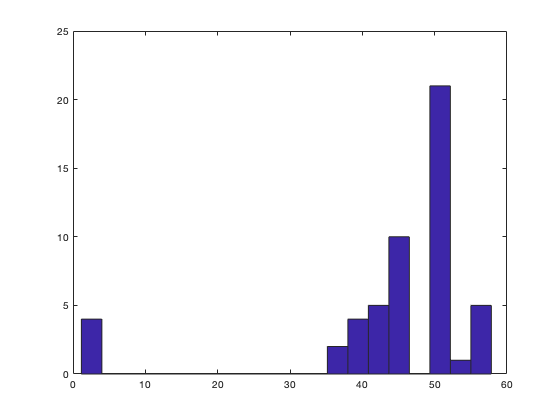

figure;
F = regionprops(segmented_mask,'MajorAxisLength');
Radii = [F.MajorAxisLength];
hist(Radii, 20);

## Count the number of coins in the image.

Since the regionprops method retuns attributes for all the identified regions in the image, we can use the size of the first dimension to count the number of coins. We find that there are 52 objects in the image. I.e 52 coins.

[m,n] = size(F);
disp(m);

    52



## Errors and Limitations

Our algorithm performs quite well on identifying the coins in the image. Which makes it quite easy to do a simple count of the number of objects in the image. The harder part is estimating the amount of money in the image. One approach is to use the area to estimate what value the object has if you know which coin has which area you can use a histogram to calculate the number of objects in a certain area range and multiply this number with the corresponding monetary value.

A problem with this method in our implementation is that for some of the overlapping coins, we create an unrealistic boundary which does not form a perfect circle. For these situations, it would be preferred to have multiple boundaries so we can extract each of the overlapping coins.

Since we have some odd boundaries as mentioned, we may not get the most accuracte estimate of the area of these particular coins which would make estimating the amount of money hard.

## Test on Bacteria.tif

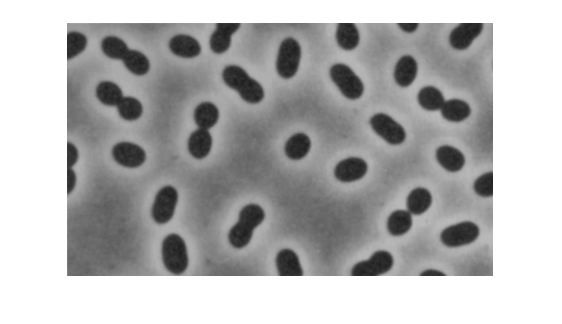

clear;
I = imread('bacteria.tif');
figure; imshow(I);

## Plot image histogram

Let's plot the histogram as well. We see that this histogram is not as well seperated as before. Let's run the same segmentation as before.

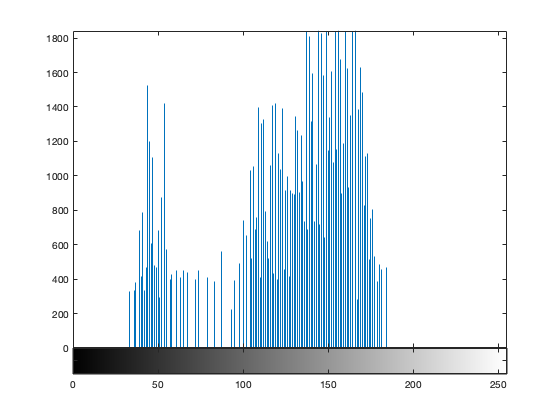

figure; imhist(I);

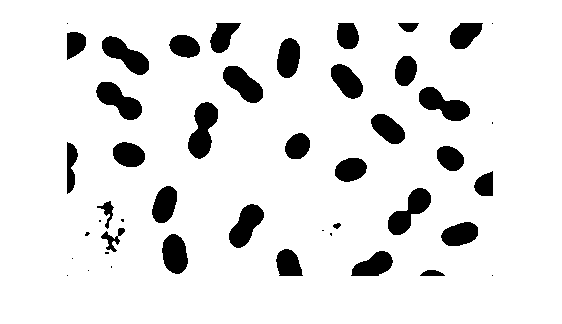

T = graythresh(I);
bI = medfilt2(im2bw(I, T));
figure; imshow(bI);

## Apply dist transform to detect coins centers

Above we saw that regular separation by threshold does not work as well in the case of the bacteria image. Let's see how this affects the dist transform.

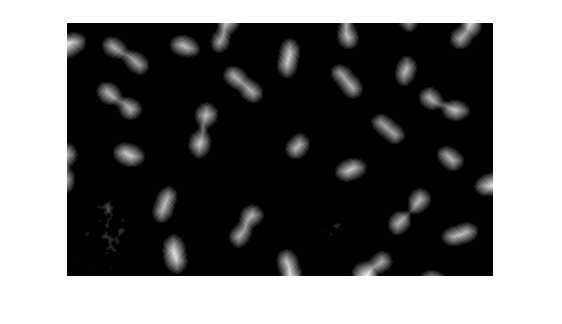

figure;
Idist = bwdist(bI, "chessboard");
imshow(Idist,[]);

## Do the last steps on the bacteria image.

We are also successful in labeling the objects

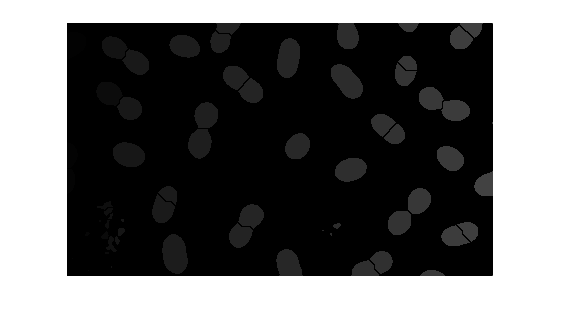

Iwshed = watershed(-Idist);
Iwshed(bI) = 0;
figure;
imshow(Iwshed);

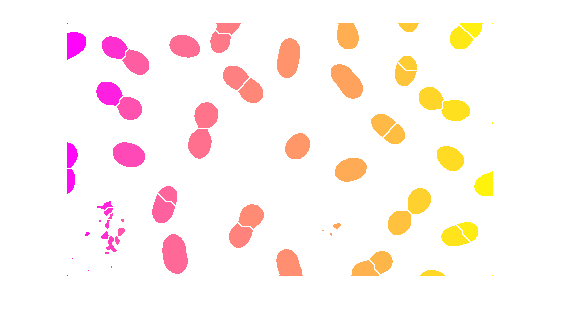



Ilabel = bwlabel(Iwshed);
Irgb = label2rgb(Ilabel,'spring');
figure;
imshow(Irgb);

## Lastly, find properties of objects

We use **regionprops** on the labeled image. We select area as the only property that we are interested in. 

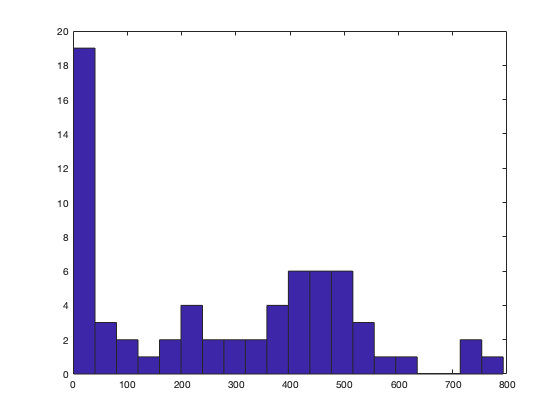

figure;
F = regionprops(Ilabel,'Area');
Areas = [F.Area];
hist(Areas, 20);

## Discussion on bacteria implementation

The method developed for coins also works quite well. But as discussed above, the histogram is not well separated. This means that the segmentation produces some irrelevant objects from the background. Using other threshold methods or filtering the background may improve the code above. We also see that the bacteria have greater overlap in some places than the coins did. Our method does not create a segmentation of these highly overlapping bacterium and would need further attention. Also, the segmentations, like in the coins, are somewhat jagged in certain places when in reality they are smoother and curved.